# Determine Is from fit of the V(I)

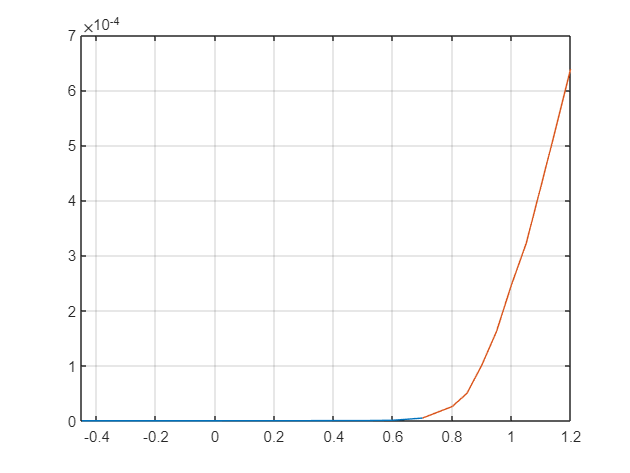

clearvars; close all
addpath(genpath('D:\Profile\qse\Files\soft\software\Matlab'));

% Import
LPath = 'D:\Profile\qse\Files\_EDMRoC pinSC\IV curve\IV curve chip\01_IV_curve_chip_spento.txt';
dummyStr = strsplit(LPath, '.');
SPath = [dummyStr{1}, '.mat'];
clear dummyStr

conv = 20e3; %Ohm

if endsWith(LPath, '.lvm')  % Dataset recorded in UTZ
    ivdata = importdata(LPath, '\t', 22);
    V = ivdata.data(:,2);
    I = ivdata.data(:,3);   %- 1e-7;
elseif endsWith(LPath, '.txt')  % Dataset recorded at SuSi building 12.8
    ivdata = importdata(LPath, '\t', 1);
    Vraw = ivdata.data(:,1);
    Iraw = ivdata.data(:,2)/conv;   
end
Iraw = Iraw + abs(Iraw(Vraw == 0));
start = 5;
V = Vraw(start:end);
I = abs(Iraw(start:end));

% Plot
figure()
plot(Vraw, Iraw, V, I)
xlim([min(Vraw) max(Vraw)])
grid()

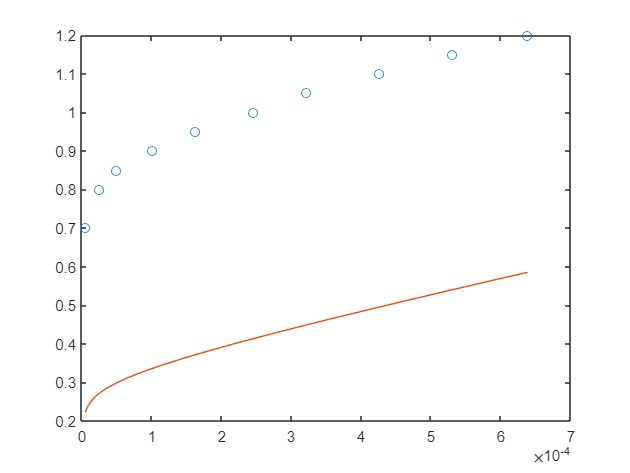

TEMPERATURE = 300;
THERMAL_VOLTAGE = 0.02585;

Rs0 = 375;
alpha0 = 1/(THERMAL_VOLTAGE * 1);
Is0 = 1;

p0 = [Rs0, alpha0, Is0];
Vmodel = @(I, C) C(1)*I + 1/C(2)*log(I/(C(3)*1e-9) + 1);

II = linspace(I(1), I(end), 1000);
figure()
plot(I, V, 'o')
hold on
plot(II, Vmodel(II, p0))


NUM_Is = 100;
Iss = linspace(0.1, 10, NUM_Is);
NUM_ALPHA = 100;
alphaMax = 1/(1.3*THERMAL_VOLTAGE);
alphaMin = 1/(1.9*THERMAL_VOLTAGE);
alphas = linspace(alphaMin, alphaMax, NUM_ALPHA);
Rs0 = 400;

Vmodel = @(I, C) C(1)*I + 1/C(2)*log(I/(C(3)*1e-12) + 1);
p0 = [Rs0, alphas(1), Iss(1)];

Vary = [200, 5, 10];
Fit = esfit(V, @(p) Vmodel(I, p), p0, Vary);

-- esfit ------------------------------------------------
Data size:                [10, 1]
Model function name:      @(p)Vmodel(I,p)
Number of fit parameters: 3
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 3 active parameters...
iteration   1: value 5.44061e-03   edge 1.00000e-01   initial simplex
iteration   2: value 5.44061e-03   edge 4.00000e+01   reflection
iteration   3: value 5.44061e-03   edge 4.44444e+01   reflection
iteration   4: value 5.44061e-03   edge 4.44444e+01   reflection
iteration   5: value 4.93624e-03   edge 4.83951e+01   reflection
iteration   6: value 4.50794e-03   edge 4.36214e+01   reflection
iteration   7: value 4.50794e-03   edge 3.62140e+01   contraction inside
iteration   8: value 3.46188e-03   edge 5.10903e+01   expansion
iteration   9: value 3.46188e-03   edge 3.69820e+01   contraction inside
iter

p0 = repmat({p0}, NUM_ALPHA, NUM_Is);
Fit = repmat({Fit}, NUM_ALPHA, NUM_Is);
for iA = 1:NUM_ALPHA
    alpha0 = alphas(iA);
    p0(iA, :) = [Rs0, alpha0, Iss(1)];
    p0_ = p0(iA, :);
    parfor iIs = 1:nIs
        Is0 = Iss(iIs);
        p0_(iIs) = [Rs0, alpha0, Is0];
        Fit{iIs, iA} = esfit(V, @(p) Vmodel(I, p), p0_(iIs), Vary);
    end
end

Conversion to cell from double is not possible.